clear;clc;close all

## First load some data

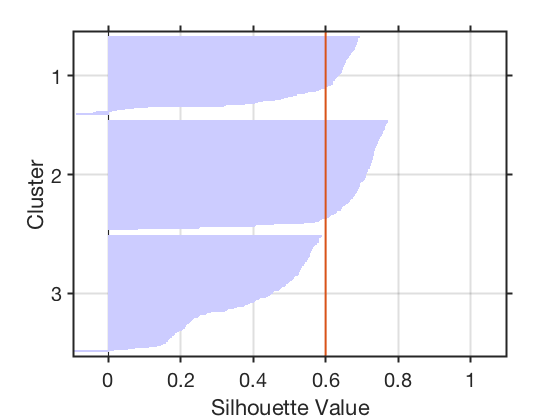

rng default  % For reproducibility
load kmeansdata
idx3 = kmeans(X,3,'Distance','cityblock');
[silh3,h] = silhouette(X,idx3,'cityblock');
h = gca;
h.Children.EdgeColor = [.8 .8 1];
yl=ylim;hold on;plot([0.6 0.6],yl,'LineWidth',2)
xlabel 'Silhouette Value'
ylabel 'Cluster'
grid on
set(gca,'FontSize',20); set(gca,'TickDir','out'); set(gca,'LineWidth',2);


size(X)

ans =    560     4


## Determine the Correct Number of Clusters

Increase the number of clusters to see if kmeans can find a better grouping of the data. This time, use the 'Display' name-value pair argument to print information about each iteration.

idx4 = kmeans(X,4, 'Distance','cityblock','Display','iter');

  iter	 phase	     num	         sum
     1	     1	     560	     1792.72
     2	     1	       6	      1771.1
Best total sum of distances = 1771.1


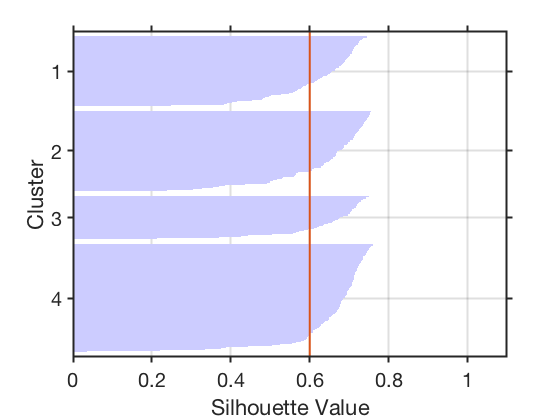

figure
[silh4,h] = silhouette(X,idx4,'cityblock');
h = gca;
h.Children.EdgeColor = [.8 .8 1];
yl=ylim;hold on;plot([0.6 0.6],yl,'LineWidth',2)
xlabel 'Silhouette Value'
ylabel 'Cluster'
grid on
set(gca,'FontSize',20); set(gca,'TickDir','out'); set(gca,'LineWidth',2);
print('-depsc2','Silhouette-4.eps');% save to an eps file

A silhouette plot for this solution indicates that these four clusters are better separated than the three in the previous solution.

## Finally, try clustering the data using five clusters.

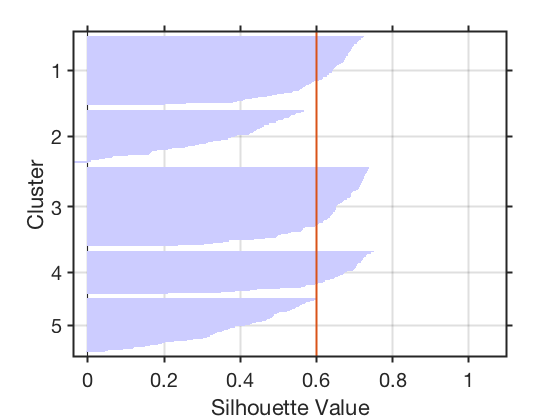

idx5 = kmeans(X,5,'Distance','cityblock','Replicates',5);
figure
[silh5,h] = silhouette(X,idx5,'city');
h = gca;
h.Children.EdgeColor = [.8 .8 1];
yl=ylim;hold on;plot([0.6 0.6],yl,'LineWidth',2)
xlabel 'Silhouette Value'
ylabel 'Cluster'
grid on
set(gca,'FontSize',20); set(gca,'TickDir','out'); set(gca,'LineWidth',2);
print('-depsc2','Silhouette-5.eps');% save to an eps file

## Quantatively compare

A more quantitative way to compare the two solutions is to look at the average silhouette values for the three cases.

cluster3 = mean(silh3)

cluster3 = 0.5352

cluster4 = mean(silh4)

cluster4 = 0.6400

cluster5 = mean(silh5)

cluster5 = 0.5266